# Examples on LQR

## First example: basic example for introduction

close all
clear
clc

A = [0 1; 0 0];
B = [0;1];
C = [1 0];

x0 = [-6 0];
Ts = 0.5;

Study reachability properties

Mr = ctrb(A,B);
rho_Mr = rank(Mr)

rho_Mr = 2

Define weights matrices for LQ design

Q = [1 0; 0 1e-3];
R = 1;

Study obs

Cq = chol(Q);
Mo = obsv(A,C);
rho_Mo = rank(Mo)

rho_Mo = 2

Go for LQR

K = lqr(A,B,Q,R)

K =     1.0000    1.4146


## Second example: Inverted Pendolum

**Exercise text removed** (course material, copyright precaution). Topic: Inverted pendulum model (nonlinear state equations, parameters, Ts) for LQ zero-regulation exercise.

**Exercise text removed** (course material, copyright precaution). Topic: Design digital LQ regulator for the linearized inverted pendulum, tune Q and R for zero regulation within tolerance in about 1 s, simulate from given initial state.

close all
clear
clc

m = 0.1;
l = 0.5;
g = 9.81;
beta = 1;

A = [0 1; g/l -beta/(m*l^2)];
B = [0 ; 1/(m*l^2)];
C = [1 0];
D = 0;

% system creation
sys = ss(A,B,C,D);
x0 = [0.02;0];

% discretization
Ts = 0.05;
sys_dt = c2d(sys,Ts,'zoh');

% get matrices of DT system
Ad = sys_dt.a;
Bd = sys_dt.b;
Cd = sys_dt.c;
Dd = sys_dt.d;

% study reachability
Mr = ctrb(Ad,Bd);
rho_Mr = rank(Mr)

rho_Mr = 2


% define Q and R
Q = [1 0; 0 1];
R = 1;

Q and R are both square matrices, with dimension of the state (Q) and the input (R)

Suggestion: choose such matrices according to diagonal shape

At this point we have no idea about the values of the state and the input, so as a first trial we choose everything equal to 1

NOTE: if we had something known in advanced we could have started with it

% study observability
Cq = chol(Q);
Mo = obsv(Ad,Cq);
rho_Mo = rank(Mo)

rho_Mo = 2

Since both matrix ranks are max => we have verified both controllability and obs!!!

So we can go with finding K

K = dlqr(Ad,Bd,Q,R);

Now we have to proceed with simulation

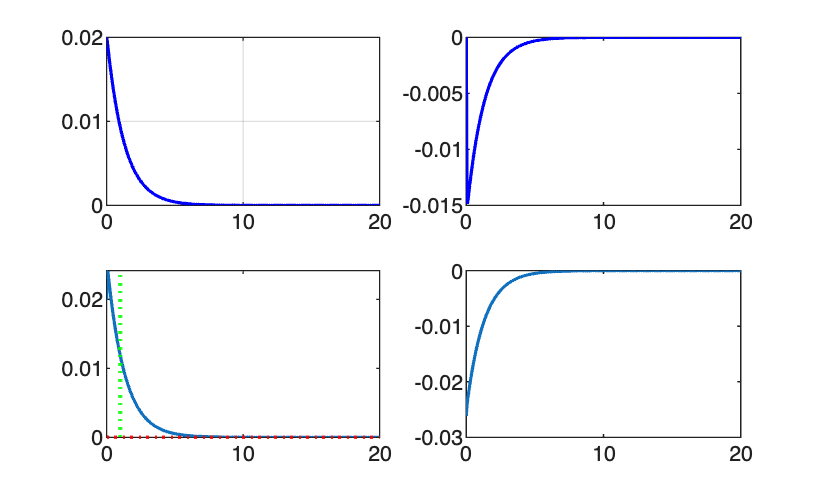

sys_x = ss(A,B,eye(2),0);

Tend = 20;

out = sim("static_feedback_basics");

x = out.x;
u = out.u;
y = out.y;

figure(1)

subplot(221)
plot(x.time,x.data(:,1),'b', 'LineWidth', 1.2);
grid on
hold on

subplot(222)
plot(x.time,x.data(:,2),'b', 'LineWidth', 1.2);

subplot(223)
plot(x.time,sqrt(x.data(:,1).^2 + x.data(:,2).^2), 'LineWidth',1.2)
yline(1e-5, ':r', 'LineWidth',1.2)
yline(-1e-5, ':r', 'LineWidth',1.2)
xline(1.05, ':g', 'LineWidth',1.2)
xline(0.95, ':g', 'LineWidth',1.2)
subplot(224)
plot(u.time, u.data, 'LineWidth',1.2)

After the first simulation, we proceed with tuning

Remember that we can change one parameter at a time (eg one entry of Q) and change it of at least an order magnitude

Q = [100 0; 0 0.1];

We continue to change parameters until we satisfy the criteria 

Let's resolve a second time the system

R = 1;

% study observability
Cq = chol(Q);
Mo = obsv(Ad,Cq);
rho_Mo = rank(Mo)

rho_Mo = 2

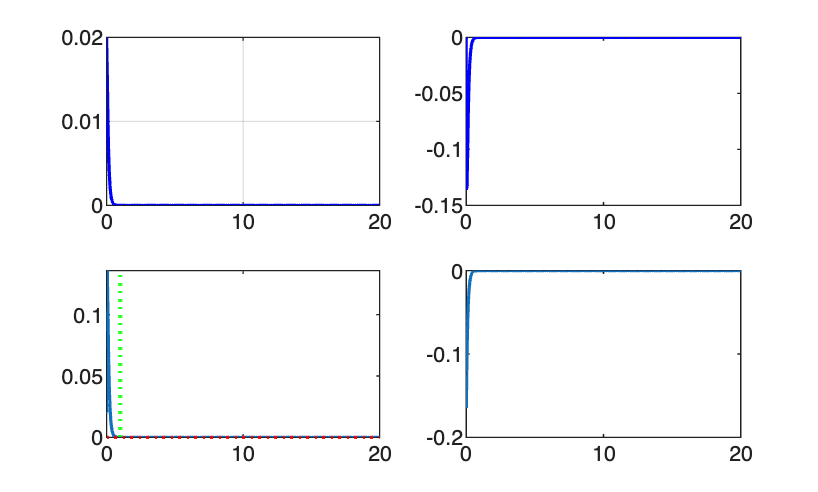


K = dlqr(Ad,Bd,Q,R);
sys_x = ss(A,B,eye(2),0);

Tend = 20;

out = sim("static_feedback_basics");

x = out.x;
u = out.u;
y = out.y;

figure(2)

subplot(221)
plot(x.time,x.data(:,1),'b', 'LineWidth', 1.2);
grid on
hold on

subplot(222)
plot(x.time,x.data(:,2),'b', 'LineWidth', 1.2);

subplot(223)
plot(x.time,sqrt(x.data(:,1).^2 + x.data(:,2).^2), 'LineWidth',1.2)
yline(1e-5, ':r', 'LineWidth',1.2)
yline(-1e-5, ':r', 'LineWidth',1.2)
xline(1.05, ':g', 'LineWidth',1.2)
xline(0.95, ':g', 'LineWidth',1.2)
subplot(224)
plot(u.time, u.data, 'LineWidth',1.2)

## Third example: Inverted pendolum with reference signal

**Exercise text removed** (course material, copyright precaution). Topic: Pendulum position tracking of a square-wave reference (period, amplitude given), zero error via integral action and 1% settling time ~0.5 s.

The first part of the exercise is equal to the previous one, just pay attention to the new value of x0

close all
clear
clc

m = 0.1;
l = 0.5;
g = 9.81;
beta = 1;

A = [0 1; g/l -beta/(m*l^2)];
B = [0 ; 1/(m*l^2)];
C = [1 0];
D = 0;

% system creation
sys = ss(A,B,C,D);
x0 = [0;0];

n = 2; % this is the state dimension

% discretization
Ts = 0.05;
sys_dt = c2d(sys,Ts,'zoh');

% get matrices of DT system
Ad = sys_dt.a;
Bd = sys_dt.b;
Cd = sys_dt.c;
Dd = sys_dt.d;

% study reachability
Mr = ctrb(Ad,Bd);
rho_Mr = rank(Mr)

rho_Mr = 2

Now the next step is to check obs wrt the choleski factorization of the augmented system (different from previous ex)

So let's build the augmented system

% see the formula on the slides

Aaug = [1 -Ts*Cd; zeros(n,1) Ad];
Baug = [0; Bd];
Caug = [0 Cd];
Daug = 0;
x0i = 0; % integrator initial condition

Now let's define our matrices Q and R, let's start with unitary weights

Q = diag(ones(1,3));
R = 1;
Cq = chol(Q);
Mo = obsv(Aaug,Cq);
rho_Mo = rank(Mo)

rho_Mo = 3

And now let's compute K

Kaug = dlqr(Aaug,Baug,Q,R)

Kaug =    -0.7212    2.0008    0.1082



% we have to split the control gain K
% (q is a scalar, so k_q is a scalar to. k_x is all the remaining
% components of Kaug)

K_q = Kaug(1);
K_x = Kaug(2:end);


Now let's simulate

sys_x = ss(A,B,eye(n),zeros(n-1));

Tend = 20;

Some info on the input:

The input is a square wave, in order to represent it in simulink, we use a pulse generator block, its parameters are the one indicated in the problem question.

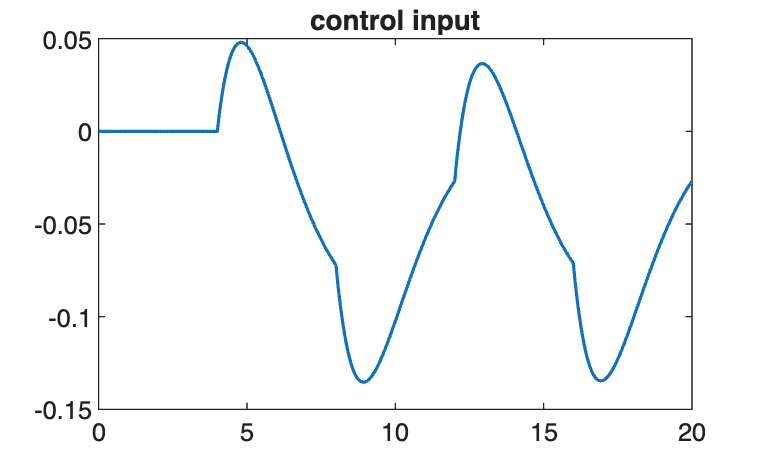

out = sim("static_feedback_basics_with_r");

x = out.x;
u = out.u;
y = out.y;
r = out.r;

figure(1)
plot(u.time, u.data, 'LineWidth',1.2)
title("control input")

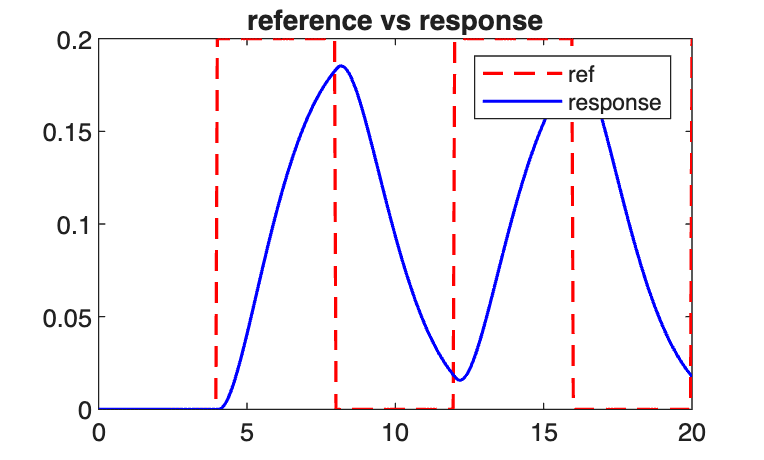


figure(2);

plot(r.time, r.data, 'r--', 'LineWidth',1.2)
hold on 
plot(y.time, y.data, 'b', 'LineWidth',1.2)
title("reference vs response")
legend("ref", "response")

We can see that the behaviour is cleary not satisfactory

We have to modify it -> the idea is quite simple: we have to act on Q, since Q is the difference of the DESIRED - ACTUAL 

If we put in our performance index more emphasis on Q parameter (increase Q value) we will have faster response!

#### Different simulation

We can increase Q by just one order of magnitude and we have to operate on the first component of Q

Simulation in class increasing Q, we are far to reach the high peak of steady state (? penso sia questo perché va su lentamente mettendo 1 1 1) of the reference -> so we have to increase the first component of Q.

We increase Q until it satisfies our requirements

clear sim

Q(1,1) = 1e5

Q =       100000           0           0
           0           1           0
           0           0           1


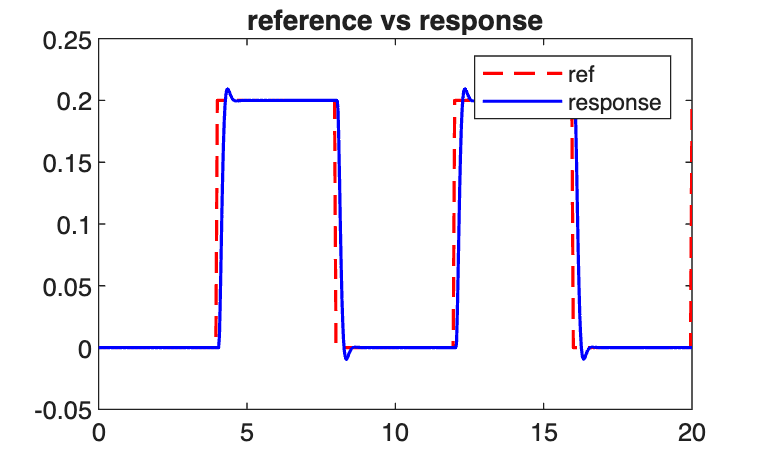

R = 1;

Cq = chol(Q);
Mo = obsv(Aaug,Cq);
rho_Mo = rank(Mo);

Kaug = dlqr(Aaug,Baug,Q,R);

K_q = Kaug(1);
K_x = Kaug(2:end);

sys_x = ss(A,B,eye(n),zeros(n-1));

Tend = 20;

out = sim("static_feedback_basics_with_r");

x = out.x;
u = out.u;
y = out.y;
r = out.r;

figure(3)

plot(r.time, r.data, 'r--', 'LineWidth',1.2)
hold on 
plot(y.time, y.data, 'b', 'LineWidth',1.2)
title("reference vs response")
legend("ref", "response")

Since we have a tolerance of 5%, we can see from the simulation that we are done!!!!

NOTE: to reach the objective fast is NOT free in practice! There must be someone that is working!!! This is the control input. So let's plot the control effort

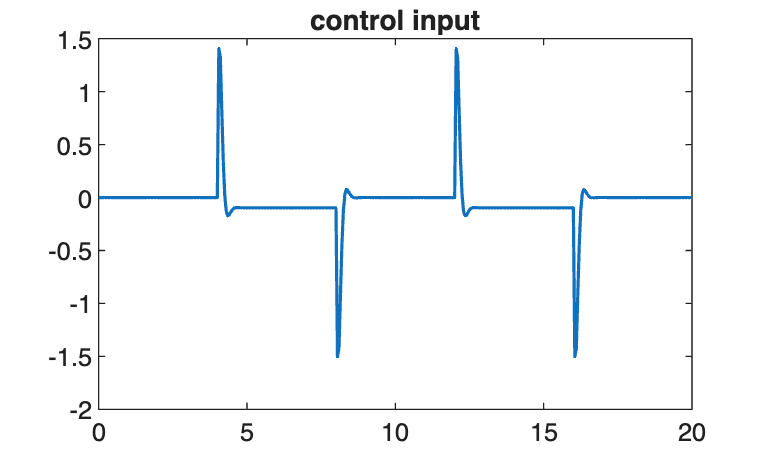

figure(4)
plot(u.time, u.data, 'LineWidth',1.2)
title("control input")

We can compare the u plots and we can clearly see that the second one is HUGE wrt the first one!!!!!

=> to reach fast tracking response we have always a COST (control input u)